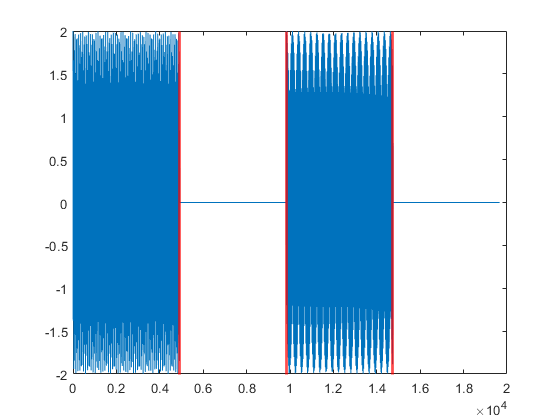

clc
clear all
close all

%Global Variables 
Fs = 16384;
dt = 1/Fs;
count = 0;
phone =[];

%load the send signal 
load sinyal.mat 

frame_dur = 0:dt:0.3-dt;
no_frame = floor(size(sinyal) / size(frame_dur));

figure
plot(sinyal);
for k=1:no_frame
    xline(length(frame_dur).* k,'Color',[1,0,0],'LineWidth',2);
end

#                                 **Cozumle**

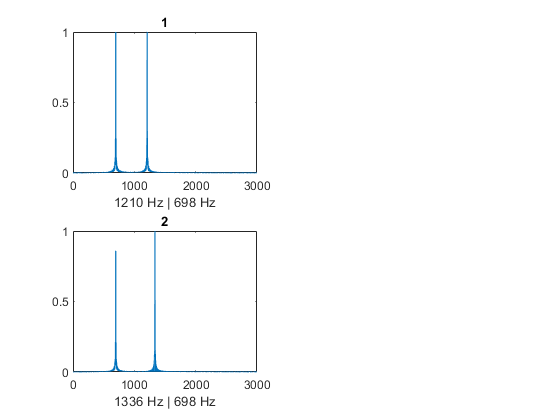


for k=1:no_frame
    frame = sinyal(((k-1)*(length(frame_dur))+1):length(frame_dur)*k);
    maxval = max(frame);
    if(maxval>0.1)
        
        %     legth of time time vector from signal
        nfft = length(frame);
        %     the next 2th power of the time
        nfft_2 = 2^nextpow2(nfft);
        
        %     fast fourier reperesentation of the signal
        ff = fft(frame,nfft_2);
        
        %     only left side of the fft signal
        fff = abs(ff(1:nfft_2/2));
        
        %Normalize  the signal to unit vector for convinence  
        fff =fff/max(fff);
        
        % Frequncy domain of the new signal
        freqss = 0:Fs/nfft_2:Fs/2-(Fs/nfft_2);
        
        %cut off frequncy for filtering(a limit between lower frq and higher freq)
        cuttoff =1050;
        
        %Normalization with nyquist frequency
        Wn = (2/Fs)*cuttoff;
        
        %Low frequency group filter
        l = fir1(128,Wn,'low');
        
        %High frequency group filter
        h = fir1(128,Wn,'high');
        
        %The filtering signal for high and low freq
        fh =fft(h,nfft_2);
        fl =fft(l,nfft_2);
        
        % the magnitude of the signal
        fh =abs(fh(1:nfft_2/2));
        fl =abs(fl(1:nfft_2/2));
        
        % product signal of the orginal signal with filtering signal of low
        % and high frequncies 
        mulh = fff.* fh;
        mull = fff.* fl;
        
        % the x value maximum and minimum value of the frequncy 
        [~,maxi] = max(mulh);
        [~,mini] = max(mull);
        
        subplot(2,ceil(no_frame/2),k);
        plot(freqss(1:1500),fff(1:1500));
        xlabel(string(freqss(maxi))+' Hz | '+string(freqss(mini))+' Hz');
       
        
        %decode the key using function decode 
        [key] = decoder([freqss(maxi),freqss(mini)]);
         title(key)
        % adding phone numbers
        phone =[phone,key];
        
        count = count +1;
    end
end

disp("Phone Number Length :"+count);

Phone Number Length :2


disp("Phone Number :"+string(phone));

Phone Number :12
